% Create a matrice containing circular pixel map
r = 10;
map = zeros((r*4)+2, (r*4)+2, "double")

map =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0 


center1 = [r, 3*r]

center1 =     10    30



focx = r+1

focx = 11

focy = 3*r+1

focy = 31


for i=1:2
    for x=focx-r:focx+r
        for y=focy-r:focy+r
            if (sqrt((x - focx)^2 + (y - focy)^2) <= r)
                map(x,y) = 1.0;
            end % end if
        end % end inner for 
    end % end mid for
    temp = focx
    focx=focy
    focy=temp
end % end outermost for

temp = 11

focx = 31

focy = 11

temp = 31

focx = 11

focy = 31

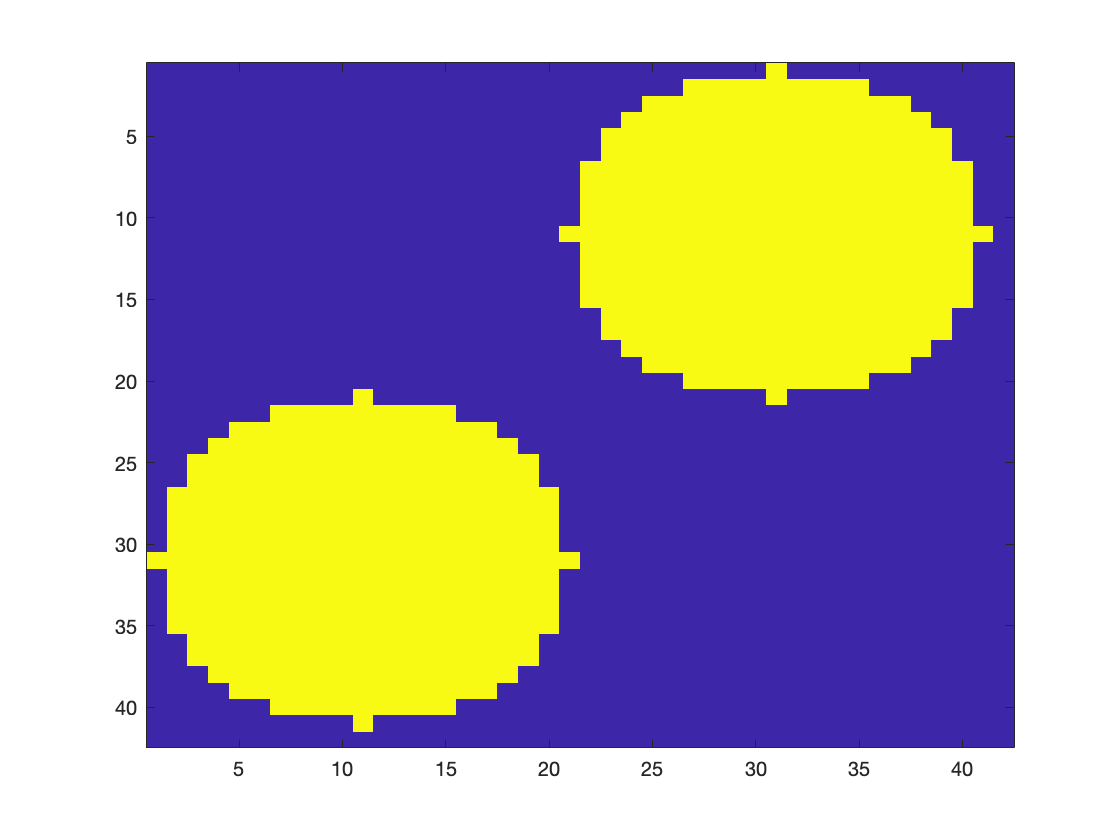

h = imagesc(map);
test = colormap(parula(256));

viscircles(center1,r, test)

Error using viscircles>validateAxes (line 269)
AX must be a valid axes handle.

Error in viscircles>parseInputs (line 193)
    ax = validateAxes(ax);

Error in <a href="matlab:matlab.internal.language.introspective.errorDocCallback('viscircles', '/Applications/MATLAB_R2020b.app/toolbox/images/imuitools/viscircles.m', 115)" style="font-weight:bold">viscircles</a